% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-08-02/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% Sample A data

file_name = "Blood_Plasma1(40x,495mW,A)_2000_30_2024-08-02-14.25.08.730.csv";
file_path = data_path+file_name;
blood_1_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,A)_2000_30_2024-08-02-14.26.42.143.csv";
file_path = strcat(data_path,file_name);
blood_2_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,A)_2000_30_2024-08-02-14.28.12.613.csv";
file_path = strcat(data_path,file_name);
blood_3_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,A)_2000_30_2024-08-02-14.29.40.893.csv";
file_path = strcat(data_path,file_name);
blood_4_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,A)_2000_30_2024-08-02-14.31.08.870.csv";
file_path = strcat(data_path,file_name);
blood_5_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,A)_2000_30_2024-08-02-14.32.43.380.csv";
file_path = strcat(data_path,file_name);
blood_6_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,A)_2000_30_2024-08-02-14.34.12.407.csv";
file_path = strcat(data_path,file_name);
blood_7_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,A)_2000_30_2024-08-02-14.35.45.150.csv";
file_path = strcat(data_path,file_name);
blood_8_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,A)_2000_30_2024-08-02-14.37.15.260.csv";
file_path = strcat(data_path,file_name);
blood_9_A = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,A)_2000_30_2024-08-02-14.38.43.467.csv";
file_path = strcat(data_path,file_name);
blood_10_A = csvread(file_path, numMetadataRows, 0);

% Sample B data

file_name = "Blood_Plasma1(40x,495mW,B)_2000_30_2024-08-02-15.03.00.037.csv";
file_path = data_path+file_name;
blood_1_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,B)_2000_30_2024-08-02-15.05.10.437.csv";
file_path = strcat(data_path,file_name);
blood_2_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,B)_2000_30_2024-08-02-15.06.53.647.csv";
file_path = strcat(data_path,file_name);
blood_3_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,B)_2000_30_2024-08-02-15.08.24.817.csv";
file_path = strcat(data_path,file_name);
blood_4_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,B)_2000_30_2024-08-02-15.09.55.410.csv";
file_path = strcat(data_path,file_name);
blood_5_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,B)_2000_30_2024-08-02-15.11.33.633.csv";
file_path = strcat(data_path,file_name);
blood_6_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,B)_2000_30_2024-08-02-15.13.08.367.csv";
file_path = strcat(data_path,file_name);
blood_7_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,B)_2000_30_2024-08-02-15.14.46.493.csv";
file_path = strcat(data_path,file_name);
blood_8_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,B)_2000_30_2024-08-02-15.16.23.610.csv";
file_path = strcat(data_path,file_name);
blood_9_B = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,B)_2000_30_2024-08-02-15.17.51.903.csv";
file_path = strcat(data_path,file_name);
blood_10_B = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(495mW,40x)_50_250_2024-08-02-13.46.28.667.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(495mW,40x)_60_250_2024-08-02-13.55.57.103.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(495mW,40x)_50_250_2024-08-02-13.51.35.117.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_A(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_A(:, blood_1_A(1, :) <= t1) = [];
blood_1_A(:, blood_1_A(1, :) >= t2) = [];
blood_2_A(:, blood_2_A(1, :) <= t1) = [];
blood_2_A(:, blood_2_A(1, :) >= t2) = [];
blood_3_A(:, blood_3_A(1, :) <= t1) = [];
blood_3_A(:, blood_3_A(1, :) >= t2) = [];
blood_4_A(:, blood_4_A(1, :) <= t1) = [];
blood_4_A(:, blood_4_A(1, :) >= t2) = [];
blood_5_A(:, blood_5_A(1, :) <= t1) = [];
blood_5_A(:, blood_5_A(1, :) >= t2) = [];
blood_6_A(:, blood_6_A(1, :) <= t1) = [];
blood_6_A(:, blood_6_A(1, :) >= t2) = [];
blood_7_A(:, blood_7_A(1, :) <= t1) = [];
blood_7_A(:, blood_7_A(1, :) >= t2) = [];
blood_8_A(:, blood_8_A(1, :) <= t1) = [];
blood_8_A(:, blood_8_A(1, :) >= t2) = [];
blood_9_A(:, blood_9_A(1, :) <= t1) = [];
blood_9_A(:, blood_9_A(1, :) >= t2) = [];
blood_10_A(:, blood_10_A(1, :) <= t1) = [];
blood_10_A(:, blood_10_A(1, :) >= t2) = [];

blood_1_B(:, blood_1_B(1, :) <= t1) = [];
blood_1_B(:, blood_1_B(1, :) >= t2) = [];
blood_2_B(:, blood_2_B(1, :) <= t1) = [];
blood_2_B(:, blood_2_B(1, :) >= t2) = [];
blood_3_B(:, blood_3_B(1, :) <= t1) = [];
blood_3_B(:, blood_3_B(1, :) >= t2) = [];
blood_4_B(:, blood_4_B(1, :) <= t1) = [];
blood_4_B(:, blood_4_B(1, :) >= t2) = [];
blood_5_B(:, blood_5_B(1, :) <= t1) = [];
blood_5_B(:, blood_5_B(1, :) >= t2) = [];
blood_6_B(:, blood_6_B(1, :) <= t1) = [];
blood_6_B(:, blood_6_B(1, :) >= t2) = [];
blood_7_B(:, blood_7_B(1, :) <= t1) = [];
blood_7_B(:, blood_7_B(1, :) >= t2) = [];
blood_8_B(:, blood_8_B(1, :) <= t1) = [];
blood_8_B(:, blood_8_B(1, :) >= t2) = [];
blood_9_B(:, blood_9_B(1, :) <= t1) = [];
blood_9_B(:, blood_9_B(1, :) >= t2) = [];
blood_10_B(:, blood_10_B(1, :) <= t1) = [];
blood_10_B(:, blood_10_B(1, :) >= t2) = [];


shifts = wavenumber;

blood1_A = blood_1_A(2:end, :);
blood2_A = blood_2_A(2:end, :);
blood3_A = blood_3_A(2:end, :);
blood4_A = blood_4_A(2:end, :);
blood5_A = blood_5_A(2:end, :);
blood6_A = blood_6_A(2:end, :);
blood7_A = blood_7_A(2:end, :);
blood8_A = blood_8_A(2:end, :);
blood9_A = blood_9_A(2:end, :);
blood10_A = blood_10_A(2:end, :);

blood1_B = blood_1_B(2:end, :);
blood2_B = blood_2_B(2:end, :);
blood3_B = blood_3_B(2:end, :);
blood4_B = blood_4_B(2:end, :);
blood5_B = blood_5_B(2:end, :);
blood6_B = blood_6_B(2:end, :);
blood7_B = blood_7_B(2:end, :);
blood8_B = blood_8_B(2:end, :);
blood9_B = blood_9_B(2:end, :);
blood10_B = blood_10_B(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

## Blood Plasma Well Trial 2024-08-02, 2x D223 50μL Sample

- Data from each well is shown, including raw data in the first plot from each section, group processed data in the second plot, and individually processed data by trial in the third plot.

- The sample was prepared by removing from the freezer, rocking for 35 minutes, and then rested for 7 minutes in the well slide.

- Samples were pipetted into 3 50μL wells and then covered with a 22mmx22mm No. 1 Cover Glass slip.

- Data was taken using a 40x immersion objective lens by using a dropper bottle to place water on the cover glass slip atop the well slide then immersing the lens in the water drop, then focusing the objective over each well using a motorized XYZ stage.

- In the 'group processed' plots, an array was made combining data from all trials in that well, and then the 'apply' function was used for processing.

- In the 'individual processing' plots, the 'apply' function was used individually on each trial, and then the resulting pre-processed data was then plotted together in a figure.

# Sample A Data

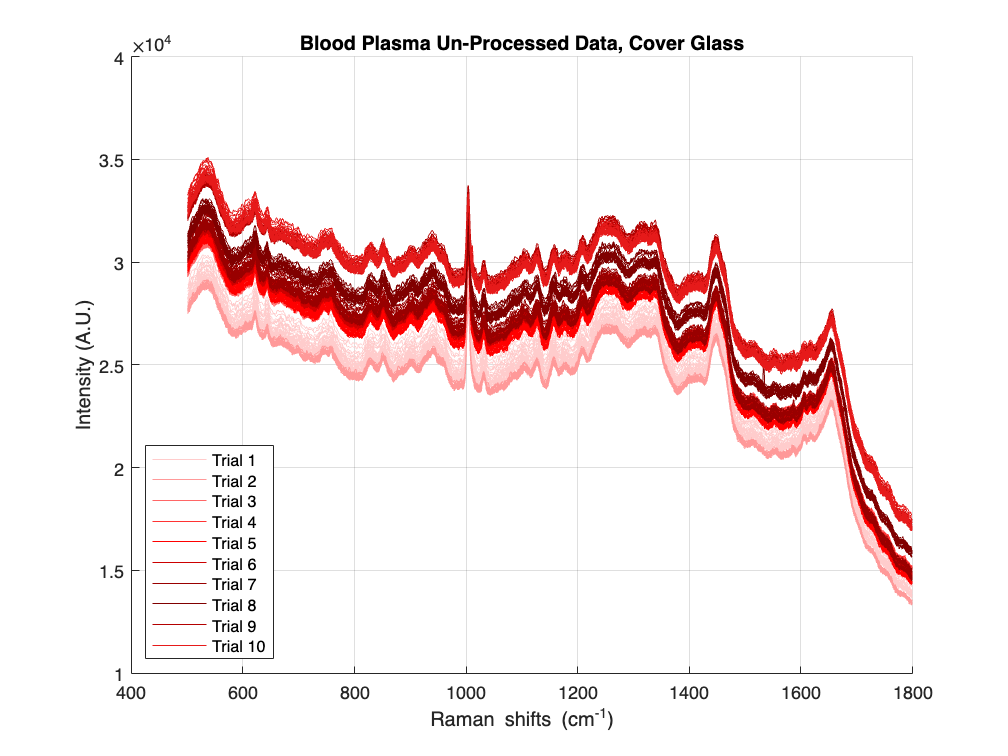

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1_A(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_A(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_A(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_A(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_A(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_A(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_A(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_A(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_A(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_A(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_A(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1_A = apply(blood1_A, [6,1,10,11,8,2,5,6,7]);
pro_blood2_A = apply(blood2_A, [6,1,10,11,8,2,5,6,7]);
pro_blood3_A = apply(blood3_A, [6,1,10,11,8,2,5,6,7]);
pro_blood4_A = apply(blood4_A, [6,1,10,11,8,2,5,6,7]);
pro_blood5_A = apply(blood5_A, [6,1,10,11,8,2,5,6,7]);
pro_blood6_A = apply(blood6_A, [6,1,10,11,8,2,5,6,7]);
pro_blood7_A = apply(blood7_A, [6,1,10,11,8,2,5,6,7]);
pro_blood8_A = apply(blood8_A, [6,1,10,11,8,2,5,6,7]);
pro_blood9_A = apply(blood9_A, [6,1,10,11,8,2,5,6,7]);
pro_blood10_A = apply(blood10_A, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_A = [blood1_A;blood2_A;blood3_A;blood4_A;blood5_A;blood6_A;blood7_A;blood8_A;blood9_A;blood10_A];
pro_blood_A = apply(blood_A, [6,1,10,11,8,2,5,6,7]);

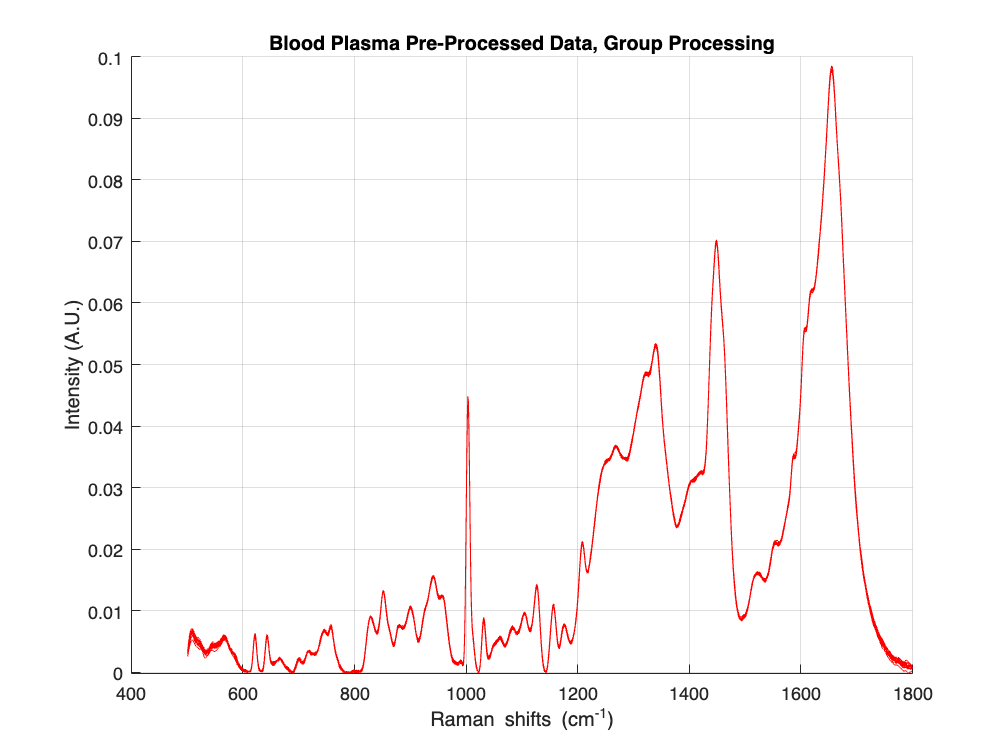

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

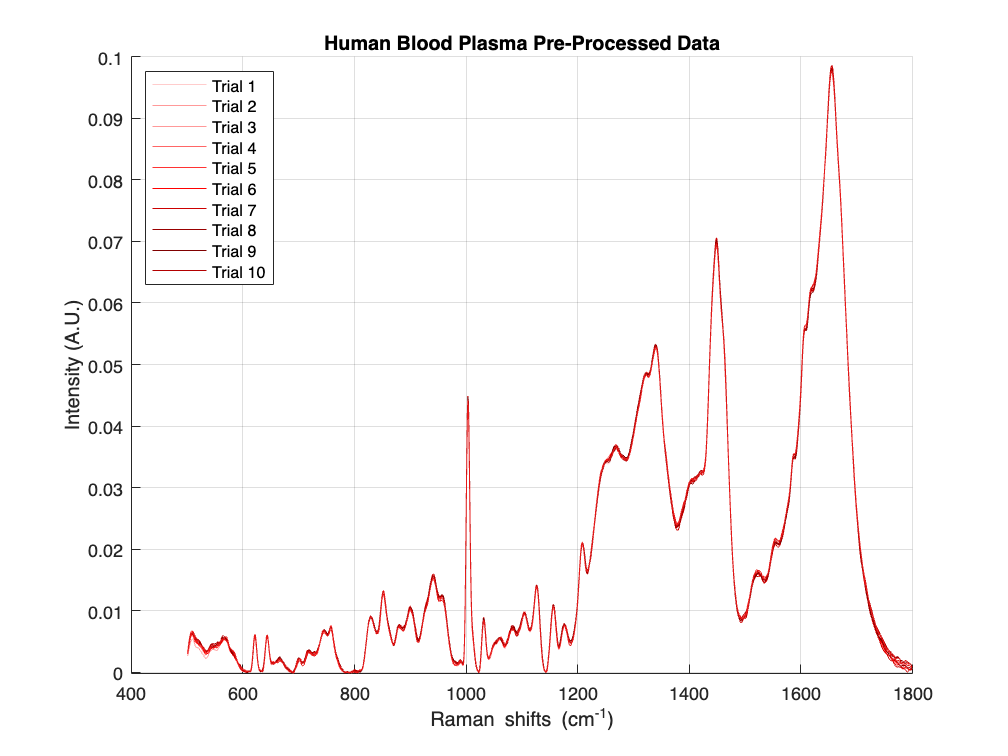

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_A, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_A, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

# Sample B Data

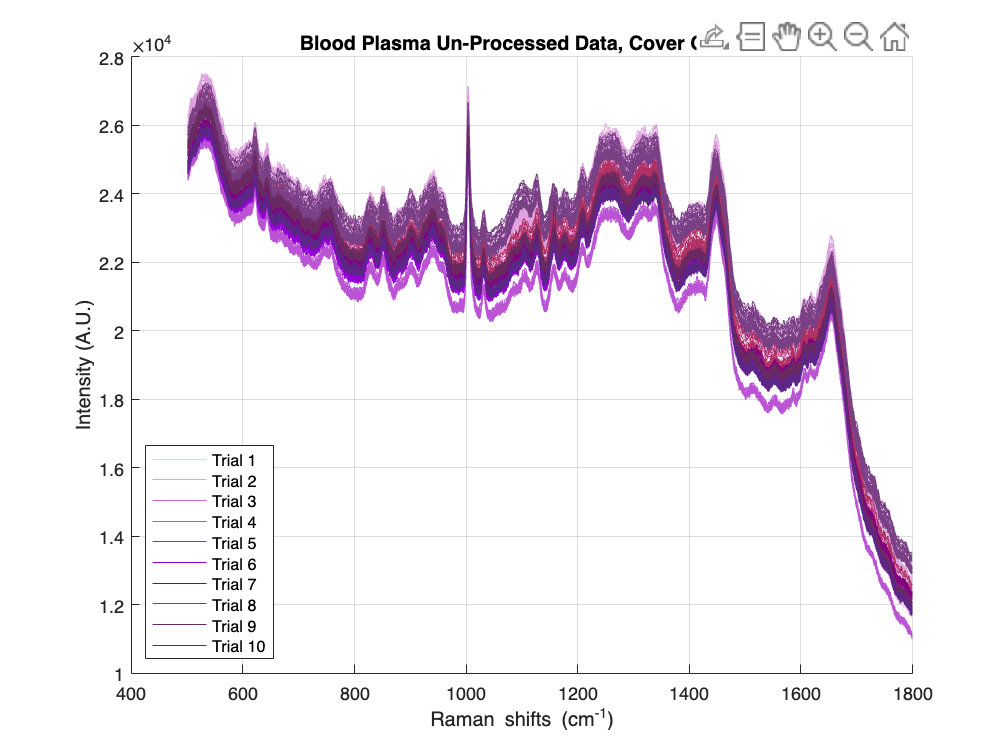

% Plotting unprocessed data

figure;
hold on;
grid on;

% Define a set of shades of purple
colors = [
    0.94, 0.80, 0.91; % Lavender Blush
    0.87, 0.63, 0.87; % Thistle
    0.80, 0.40, 0.80; % Orchid
    0.73, 0.33, 0.83; % Amethyst
    0.69, 0.19, 0.38; % Plum
    0.58, 0.00, 0.83; % Dark Violet
    0.50, 0.00, 0.50; % Purple
    0.48, 0.25, 0.52; % Blue Violet
    0.41, 0.16, 0.38; % Dark Orchid
    0.36, 0.15, 0.53  % Indigo
];

% Plot each trial with the specified colors
plot(wavenumber, blood1_B(1,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B(1,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B(1,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B(1,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B(1,:), 'Color', colors(5,:));
plot(wavenumber, blood6_B(1,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B(1,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B(1,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B(1,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B(1,:), 'Color', colors(10,:));

% Plot remaining data for each trial
plot(wavenumber, blood1_B(2:end,:), 'Color', colors(1,:));
plot(wavenumber, blood2_B(2:end,:), 'Color', colors(2,:));
plot(wavenumber, blood3_B(2:end,:), 'Color', colors(3,:));
plot(wavenumber, blood4_B(2:end,:), 'Color', colors(4,:));
plot(wavenumber, blood5_B(2:end,:), 'Color', colors(5,:));
plot(wavenumber, blood6_B(2:end,:), 'Color', colors(6,:));
plot(wavenumber, blood7_B(2:end,:), 'Color', colors(7,:));
plot(wavenumber, blood8_B(2:end,:), 'Color', colors(8,:));
plot(wavenumber, blood9_B(2:end,:), 'Color', colors(9,:));
plot(wavenumber, blood10_B(2:end,:), 'Color', colors(10,:));

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1_B = apply(blood1_B, [6,1,10,11,8,2,5,6,7]);
pro_blood2_B = apply(blood2_B, [6,1,10,11,8,2,5,6,7]);
pro_blood3_B = apply(blood3_B, [6,1,10,11,8,2,5,6,7]);
pro_blood4_B = apply(blood4_B, [6,1,10,11,8,2,5,6,7]);
pro_blood5_B = apply(blood5_B, [6,1,10,11,8,2,5,6,7]);
pro_blood6_B = apply(blood6_B, [6,1,10,11,8,2,5,6,7]);
pro_blood7_B = apply(blood7_B, [6,1,10,11,8,2,5,6,7]);
pro_blood8_B = apply(blood8_B, [6,1,10,11,8,2,5,6,7]);
pro_blood9_B = apply(blood9_B, [6,1,10,11,8,2,5,6,7]);
pro_blood10_B = apply(blood10_B, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_B = [blood1_B;blood2_B;blood3_B;blood4_B;blood5_B;blood6_B;blood7_B;blood8_B;blood9_B;blood10_B];
pro_blood_B = apply(blood_B, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_B, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_B, 'Color', [0 0 1]); % Blue
plot(wavenumber, pro_blood2_B, 'Color', [1 0 0]); % Red
plot(wavenumber, pro_blood3_B, 'Color', [0 1 0]); % Green
plot(wavenumber, pro_blood4_B, 'Color', [1 0 1]); % Magenta
plot(wavenumber, pro_blood5_B, 'Color', [0 1 1]); % Cyan
plot(wavenumber, pro_blood6_B, 'Color', [0 0 0]); % Black
plot(wavenumber, pro_blood7_B, 'Color', [1 1 0]); % Yellow
plot(wavenumber, pro_blood8_B, 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, pro_blood9_B, 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, pro_blood10_B, 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

# Comparison

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A, '-r');
plot(wavenumber, pro_blood_B, '-b');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;
figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_A, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_A, 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, pro_blood1_B, '-b');
plot(wavenumber, pro_blood2_B, '-b');
plot(wavenumber, pro_blood3_B, '-b');
plot(wavenumber, pro_blood4_B, '-b');
plot(wavenumber, pro_blood5_B, '-b');
plot(wavenumber, pro_blood6_B, '-b');
plot(wavenumber, pro_blood7_B, '-b');
%plot(wavenumber, pro_blood8_B, '-b');
plot(wavenumber, pro_blood9_B, '-b');
plot(wavenumber, pro_blood10_B, '-b');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

# Comparison vs. Collection 4

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-08-06/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

% well 1 data

file_name = "Blood_Plasma1(40x,495mW,Well1)_2000_30_2024-07-25-14.05.15.270.csv";
file_path = data_path+file_name;
blood_1_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well1)_2000_30_2024-07-25-14.06.46.857.csv";
file_path = strcat(data_path,file_name);
blood_2_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well1)_2000_30_2024-07-25-14.08.19.973.csv";
file_path = strcat(data_path,file_name);
blood_3_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well1)_2000_30_2024-07-25-14.09.54.200.csv";
file_path = strcat(data_path,file_name);
blood_4_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well1)_2000_30_2024-07-25-14.11.27.703.csv";
file_path = strcat(data_path,file_name);
blood_5_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well1)_2000_30_2024-07-25-14.13.11.530.csv";
file_path = strcat(data_path,file_name);
blood_6_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well1)_2000_30_2024-07-25-14.14.49.133.csv";
file_path = strcat(data_path,file_name);
blood_7_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well1)_2000_30_2024-07-25-14.16.26.297.csv";
file_path = strcat(data_path,file_name);
blood_8_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well1)_2000_30_2024-07-25-14.18.03.237.csv";
file_path = strcat(data_path,file_name);
blood_9_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well1)_2000_30_2024-07-25-14.19.38.440.csv";
file_path = strcat(data_path,file_name);
blood_10_1 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-07-25-13.25.42.187.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-07-25-13.35.03.900.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-07-25-13.39.18.243.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_1(:, blood_1_1(1, :) <= t1) = [];
blood_1_1(:, blood_1_1(1, :) >= t2) = [];
blood_2_1(:, blood_2_1(1, :) <= t1) = [];
blood_2_1(:, blood_2_1(1, :) >= t2) = [];
blood_3_1(:, blood_3_1(1, :) <= t1) = [];
blood_3_1(:, blood_3_1(1, :) >= t2) = [];
blood_4_1(:, blood_4_1(1, :) <= t1) = [];
blood_4_1(:, blood_4_1(1, :) >= t2) = [];
blood_5_1(:, blood_5_1(1, :) <= t1) = [];
blood_5_1(:, blood_5_1(1, :) >= t2) = [];
blood_6_1(:, blood_6_1(1, :) <= t1) = [];
blood_6_1(:, blood_6_1(1, :) >= t2) = [];
blood_7_1(:, blood_7_1(1, :) <= t1) = [];
blood_7_1(:, blood_7_1(1, :) >= t2) = [];
blood_8_1(:, blood_8_1(1, :) <= t1) = [];
blood_8_1(:, blood_8_1(1, :) >= t2) = [];
blood_9_1(:, blood_9_1(1, :) <= t1) = [];
blood_9_1(:, blood_9_1(1, :) >= t2) = [];
blood_10_1(:, blood_10_1(1, :) <= t1) = [];
blood_10_1(:, blood_10_1(1, :) >= t2) = [];

shifts = wavenumber;

blood1_1 = blood_1_1(2:end, :);
blood2_1 = blood_2_1(2:end, :);
blood3_1 = blood_3_1(2:end, :);
blood4_1 = blood_4_1(2:end, :);
blood5_1 = blood_5_1(2:end, :);
blood6_1 = blood_6_1(2:end, :);
blood7_1 = blood_7_1(2:end, :);
blood8_1 = blood_8_1(2:end, :);
blood9_1 = blood_9_1(2:end, :);
blood10_1 = blood_10_1(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

% Preprocessing the data

pro_blood1_1 = apply(blood1_1, [6,1,10,11,8,2,5,6,7]);
pro_blood2_1 = apply(blood2_1, [6,1,10,11,8,2,5,6,7]);
pro_blood3_1 = apply(blood3_1, [6,1,10,11,8,2,5,6,7]);
pro_blood4_1 = apply(blood4_1, [6,1,10,11,8,2,5,6,7]);
pro_blood5_1 = apply(blood5_1, [6,1,10,11,8,2,5,6,7]);
pro_blood6_1 = apply(blood6_1, [6,1,10,11,8,2,5,6,7]);
pro_blood7_1 = apply(blood7_1, [6,1,10,11,8,2,5,6,7]);
pro_blood8_1 = apply(blood8_1, [6,1,10,11,8,2,5,6,7]);
pro_blood9_1 = apply(blood9_1, [6,1,10,11,8,2,5,6,7]);
pro_blood10_1 = apply(blood10_1, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_1 = [blood1_1;blood2_1;blood3_1;blood4_1;blood5_1;blood6_1;blood7_1;blood8_1;blood9_1;blood10_1];
pro_blood_1 = apply(blood_1, [6,1,10,11,8,2,5,6,7]);

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_A, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_A, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_A, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_A, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_A, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_A, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_A, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_A, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_A, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_A, 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, pro_blood1_B, '-b');
plot(wavenumber, pro_blood2_B, '-b');
plot(wavenumber, pro_blood3_B, '-b');
plot(wavenumber, pro_blood4_B, '-b');
plot(wavenumber, pro_blood5_B, '-b');
plot(wavenumber, pro_blood6_B, '-b');
plot(wavenumber, pro_blood7_B, '-b');
plot(wavenumber, pro_blood8_B, '-b');
plot(wavenumber, pro_blood9_B, '-b');
plot(wavenumber, pro_blood10_B, '-b');
plot(wavenumber, pro_blood1_1, '-g');
plot(wavenumber, pro_blood2_1, '-g');
plot(wavenumber, pro_blood3_1, '-g');
plot(wavenumber, pro_blood4_1, '-g');
plot(wavenumber, pro_blood5_1, '-g');
plot(wavenumber, pro_blood6_1, '-g');
plot(wavenumber, pro_blood7_1, '-g');
plot(wavenumber, pro_blood8_1, '-g');
plot(wavenumber, pro_blood9_1, '-g');
plot(wavenumber, pro_blood10_1, '-g');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;
figure;
hold on;
grid on;
plot(wavenumber, pro_blood_A, '-r');
plot(wavenumber, pro_blood_B, '-b');
plot(wavenumber, pro_blood_1, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
hold off;

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end
